load('./traces/input.mat');
results = zeros(size(inputs_a,1),1);

for i = 1 : size(inputs_a,1)
    results(i) = hex2dec(inputs_a(i,:)) * hex2dec(inputs_b(i,:));
end 

hwResults = hammingWeight(results)'

hwResults =     14    12    16    19    17    15    14    15    15    21    16    15    14    14    17    17    13    20    15    13    14    17    14    16    18    22    17    19    17    14    17    15    16    18    17    14    18    17    18    18     9    11    18    15    21    17    18    19    10    15


Create some random vectors for hamming weights

randomHw = randi([0,44],1000,size(traces_Y,1)) 

randomHw =     24     0    41    14    33    39    19    22    18    17     7    12    31    38    29     2     6     8    35    13    25    30    28     9    27    21    44    36    33    26    43    30     9    11    10    20    14    39    30     5    15    27    13    32    31    42    16    20    37    21
    38     8    12    39     5    21     6    39     0    25     4    37    13    27    15     4     2    35     6    22    39    30    26    30    36     3    31    20    20    19    10    37    34    26    29    14    35    16    33     6    13    31    27    26    32    12    18    23     3    33
    21    24     4    19    38    42    24     5    38    41    21    13     4    40     0    33    36    31    20    24    30    44    31     8    38     7    31    19    14    35    35    25    13     4    40    23     5    27    22     8    20    21     5    18    11    43     7    29     0    24
    44     1    32     5     1    30    30    40     4    13     8    34    16    22  

**One must average the whole measure to match with the size of the hamming weight vector**

meanTraces = mean(traces_Y,2)';

corrMatrix = corrcoef(meanTraces,hwResults)

corrMatrix =    1.000000000000000   0.019345759668019
   0.019345759668019   1.000000000000000


corrTrue = corrMatrix(1,2)

corrTrue =    0.019345759668019


corrFalse = zeros(1,1000);
for i = 1 : 1000
    corrMatrix = corrcoef(meanTraces,randomHw(i,:));
    corrFalse(i) = corrMatrix(1,2);
end

**Plot**

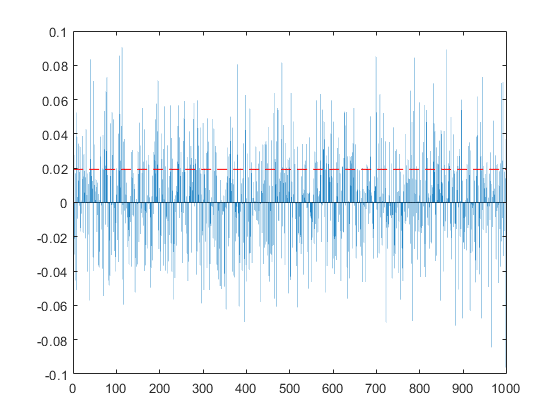

bar(corrFalse)
hold on
line([0 1000],[corrTrue corrTrue],'Color','red','LineStyle','--')
hold off

Evidently this system does not work

**Maybe there is a sample that leaks the most correlation ?**

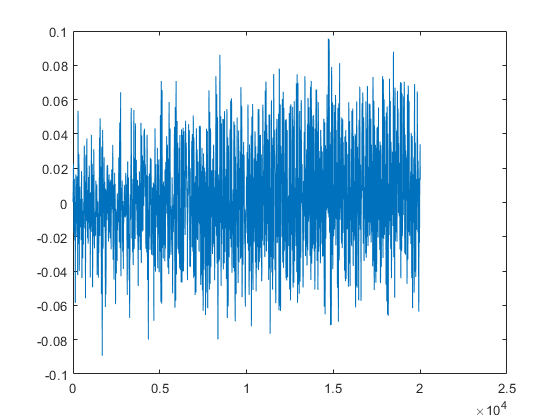

corrTrueCoefs = zeros(1,size(traces_Y,2));
for i = 1 : length(corrTrueCoefs)
    trace = traces_Y(:,i)';
    corrMatrix = corrcoef(trace,hwResults);
    corrTrueCoefs(i) = corrMatrix(1,2);
end

plot(corrTrueCoefs)


% xlim([1807 2048])
% ylim([0.0541 0.1150])

Either work with the max or average those samples that have the most correlation

**Average**

First the average of those samples. Choose those samples that have correlation above 0.1.

highCorrTraces = traces_Y(:,corrTrueCoefs >= 0.1);
meanHighCorrTraces = mean(highCorrTraces,2);
corrMatrix = corrcoef(meanHighCorrTraces,hwResults);
highCorrTrue = corrMatrix(1,2);
fprintf("Correlation with average of values over 0.1 only: %d",highCorrTrue);

Correlation with average of values over 0.1 only: NaN

Compare

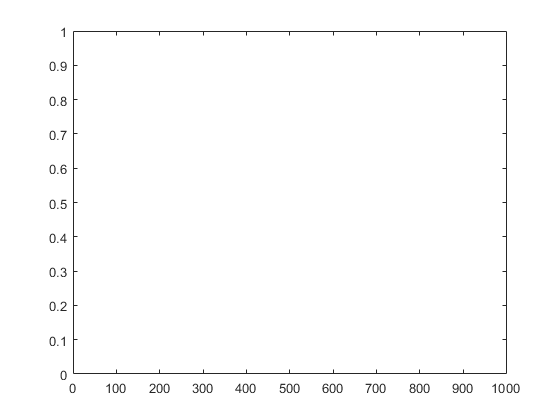

for i = 1 : 1000
    corrMatrix = corrcoef(meanHighCorrTraces,randomHw(i,:));
    corrFalse(i) = corrMatrix(1,2);
end

bar(corrFalse)
hold on
line([0 1000],[highCorrTrue highCorrTrue],'Color','red','LineStyle','--')
hold off

Calculate difference and calculate mean and variance

diffCorrFalse = corrFalse - highCorrTrue;
mean(diffCorrFalse)

ans =    NaN


var(diffCorrFalse)

ans =    NaN


**Max**

[~,index] = max(corrTrueCoefs);
highCorrTraces = traces_Y(:,index);
meanHighCorrTraces = mean(highCorrTraces,2);
corrMatrix = corrcoef(meanHighCorrTraces,hwResults);
highCorrTrue = corrMatrix(1,2);
fprintf("Correlation with max sample value only: %d",highCorrTrue);

Correlation with max sample value only: 9.562226e-02

Compare

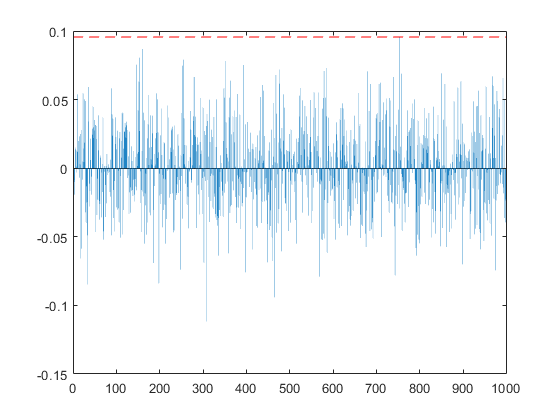

corrFalse = zeros(size(corrFalse));
for i = 1 : 1000
    corrMatrix = corrcoef(meanHighCorrTraces,randomHw(i,:));
    corrFalse(i) = corrMatrix(1,2);
end

bar(corrFalse)
hold on
line([0 1000],[highCorrTrue highCorrTrue],'Color','red','LineStyle','--')
hold off

Calculate difference and calculate mean and variance

diffCorrFalse = corrFalse - highCorrTrue;
mean(diffCorrFalse)

ans =   -0.094758335163527


var(diffCorrFalse)

ans =      9.365415246063652e-04
